n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 5; 
%%%%%%%%%%%%
sep = 5;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

p_vec =  linspace(1,50,50)*100;
n_rep = 100;
n_pararell = 10;
n_p_chunk = 50/n_pararell;
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end

tic
% parallel for loop
parfor w = 1 : n_pararell
    for i = 1:length(p_vec_chunk{w})
    p = p_vec_chunk{w}(i)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
        % iterate
 
        clustering_acc_mat_chunk{w}(j, i) = iterative_kmeans_spectral_init_ver_01_11_24(x, sigma, K,  n_iter, rounding, cluster_true);
    end
end
end


ans =

  1x0 empty double row vector


ans =

     7    64   649


ans =

     9

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

ans =

     1     2     3     4     5     6     7     8     9    10   931


ans =

        4431

ans =

     7     9


ans =

     1     2     3     4     5     6     7     8     9    10   304   488



ans =

     1     2     3     4     5     6     7     8     9    10


  breakyes = 1.0,  maxresidual < 1.00e-04
  breakyes = 1.0,  maxresidual < 1.00e-04

ans =

     1     2     3     4     5     6     7     8     9    10



ans =

     1     2     4     5     6     7     8     9    10


  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=2.84e-06,dualfeasorg=2.47e-05
ans =

     1     2     3     4     5     6     7     8     9    10

ans =

     1     2     3     4     5     6     7     8     9    10

  breakyes = 1.0,  maxresidual < 1.00e-04

ans =

toc


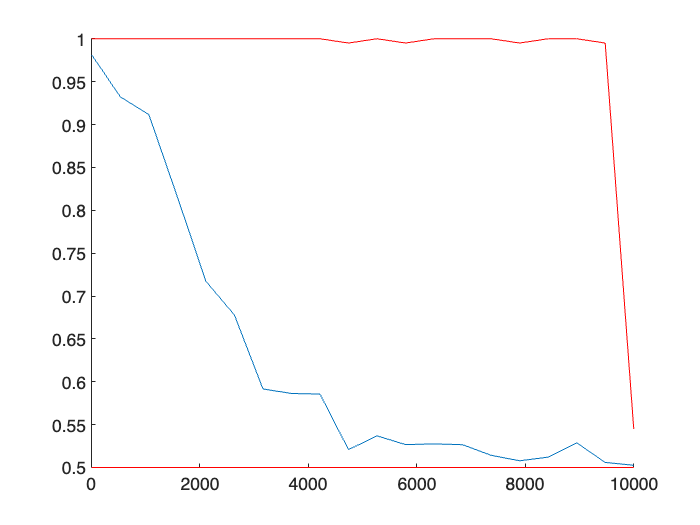

clustering_acc_mat = [];
for i = 1:n_pararell
    clustering_acc_mat = [clustering_acc_mat, clustering_acc_mat_chunk{i}];
    x = p_vec;                     
    y = mean(clustering_acc_mat,1);
    y_max = max(clustering_acc_mat);
    y_min = min(clustering_acc_mat);
end

figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off